# MLP

#### generate data

numSamples = 20;
numNeurons = 5;
[X,Xtrain,Ytrain,fig,f] = data_generator(numSamples);

#### create a neural network

net = feedforwardnet(numNeurons);

#### set early stopping parameters 

net.divideParam.trainRatio = 1.0; % training set [%]
net.divideParam.valRatio = 0.0; % validation set [%]
net.divideParam.testRatio = 0.0; % test set [%]

#### train a neural network

net.trainParam.epochs = 200;
net = train(net, Xtrain, Ytrain);

% view net

view (net)

% simulate a network over complete input range

Y = net(X);
Y_true = f(X);
rmse = @(y_pred, y_true) sqrt(mean((y_pred - y_true).^2));

% plot network response

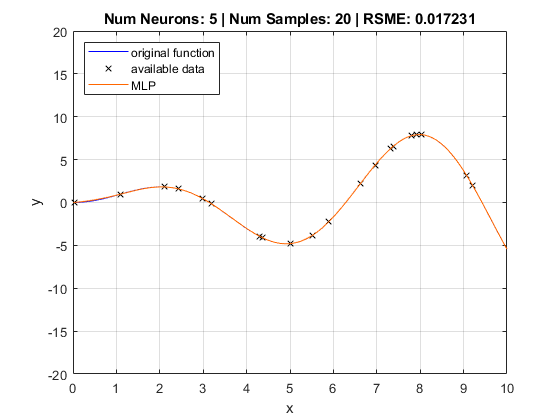

figure(fig)
plot(X,Y,'color',[1 .4 0])
legend('original function','available data','MLP','location','northwest')
title("Num Neurons: " + string(numNeurons) + " | Num Samples: " + string(numSamples) + " | RSME: "+ string(rmse(Y, Y_true)));

# Data generator 				

#### `Data generator function`

function [X,Xtrain,Ytrain,fig,f] = data_generator(numSamples) 				

#### `data generator`

f = @(x) x .* sin(x);

X = 0.01:.01:10;
Y = f(X);

fig = figure;
plot(X, Y, 'b-')
hold on
grid on 				

#### `available data points`

seed = 15;

Xtrain = randsample(RandStream("v5uniform", "Seed", seed), X, numSamples);
Ytrain = f(Xtrain);

plot(Xtrain, Ytrain, 'kx')
xlabel('x')
ylabel('y')
ylim([-20 20])
legend('original function','available data','location','northwest')
end